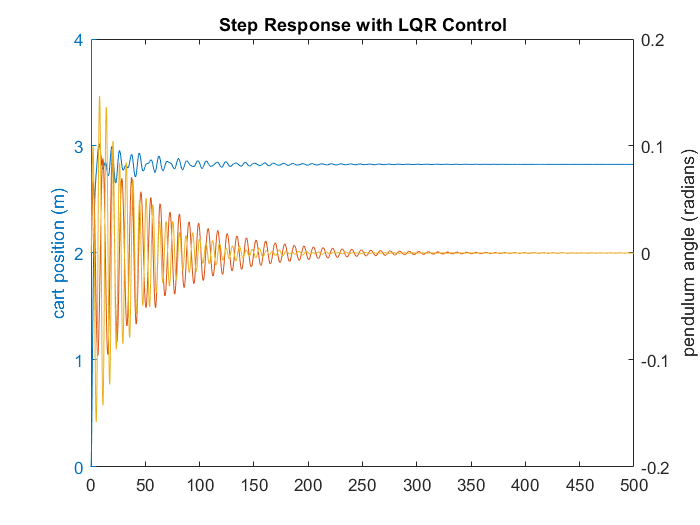

%% First Component: Part D

% Given Parameters 
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.8;

% State Space Matrices
A = [0 1 0 0 0 0 ;
     0 0 ((-m1*g)/M) 0 (-m2*g)/M 0;
     0 0 0 1 0 0;
     0 0 ((-g*(m1+M))/(M*l1)) 0 (-g*(m2)/(M*l1)) 0;
     0 0 0 0 0 1;
     0 0 (-g*(m1))/(M*l2) 0 (-g*(m2+M)/(M*l2)) 0];
B = [0; 1/M; 0 ; 1/(M*l1); 0 ; 1/(M*l2)];
C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0];
D = [0; 0; 0];

states = {'x' 'x_dot' 'theta1' 'theta1_dot' 'theta2' 'theta2_dot'};
inputs = {'u'};
outputs = {'x'; 'theta1'; 'theta2'};

% Giving in constants for LQR
Q = (C'*C);
Q(1,1) = 500000;
Q(3,3) = 500;
Q(5,5) = 500;
R = 1;
[K,S,E] = lqr(A,B,Q,R);
Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];

states = {'x' 'x_dot' 'theta1' 'theta1_dot' 'theta2' 'theta2_dot'};
inputs = {'r'};
outputs = {'x'; 'theta1' ;'theta2'};
sys_cl = ss(Ac,Bc,Cc,Dc,'statename',states,'inputname',inputs,'outputname',outputs);

% Plotting the Graph 
t = 0:0.1:500;
r =2000*ones(size(t));
[y,t,x]=lsim(sys_cl,r,t);
[AX,H1,H2] = plotyy(t,y(:,1),[t,t],[y(:,2),y(:,3)],'plot');
set(get(AX(1),'Ylabel'),'String','cart position (m)');
set(get(AX(2),'Ylabel'),'String','pendulum angle (radians)');
title('Step Response with LQR Control');